# Visual Objects

[Open live script](matlab:edit physvis_toolbox_visual_objects)

To create a visual object (such as a Point, Curve, Box, or Sphere), give it a name (such as myBall) to refer to it again later.

myBall =   Sphere with properties:

            Radius: 1
            Retain: 10
          HasTrail: 0
         TrailType: 'points'
       TrailRadius: 0.2500
              Axis: [1 0 0]
                Up: [0 1 0]
       TrailObject: []
    IdentityMatrix: [4×4 double]
             Color: [0 1 0]
            Canvas: [1×1 physvis.Canvas]
             Alpha: 1
               Red: 0
             Green: 1
              Blue: 0
           Visible: 'on'
          UserData: []
                 X: 0
                 Y: 0
                 Z: 0
          Position: [0 0 0]


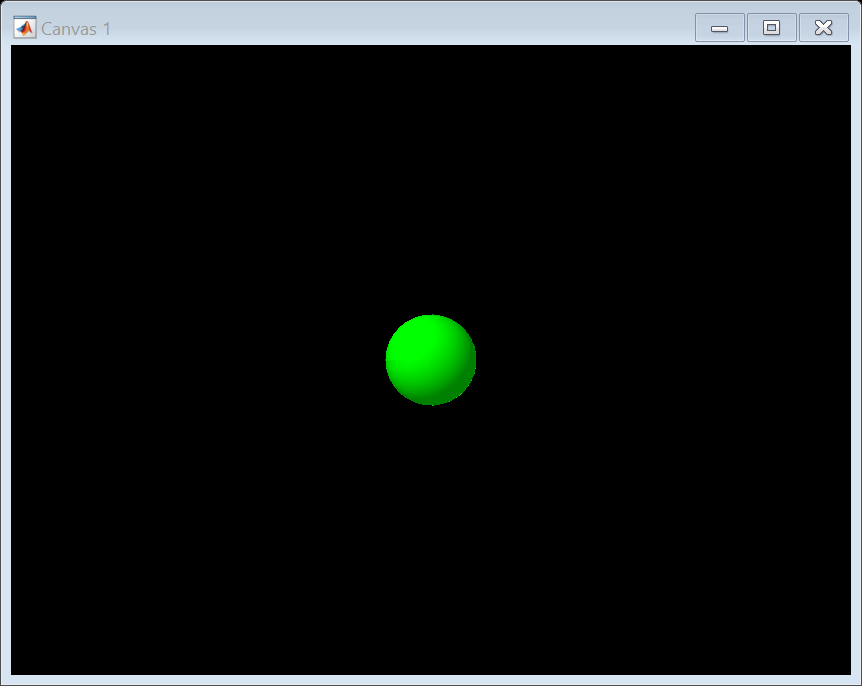

myBall = physvis.Sphere('Radius', 1, 'Color', Colors.green)

All objects have properties like myBall.Position, myBall.Color, and myBall.Radius or other dimensional characteristics. If you change a property of an object, PHYSVIS will automatically update the scene in the figure window.

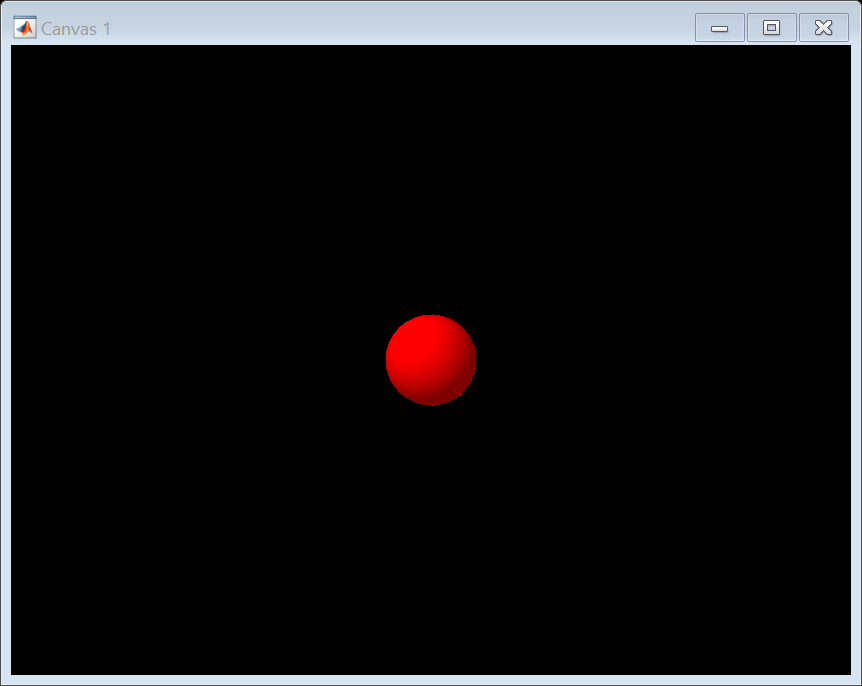

myBall.Color = Colors.red;

To add a new custom property to a PHYSVIS object (such as a physical property like mass), attach it to the UserData property,

myBall.UserData.Mass = 1;

To create an array of visual objects of the same type, separate the elements with either a comma or a space

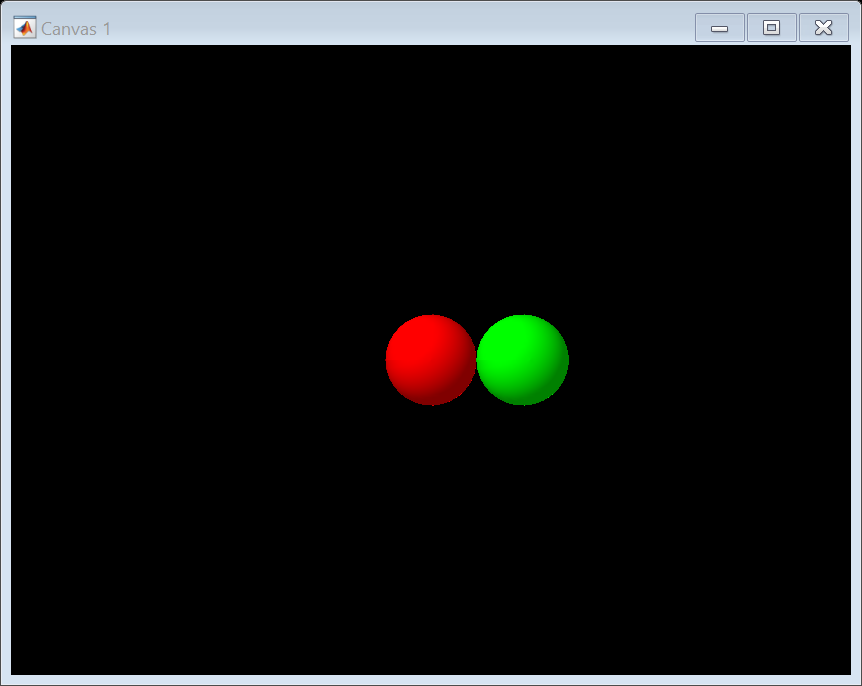

myOtherBall = physvis.Sphere('Position', [2 0 0], 'Radius', 1, 'Color', Colors.green);

myBallSet = [myBall myOtherBall];

To refer to a particular element in an array of visual objects, specify a subscript, such as

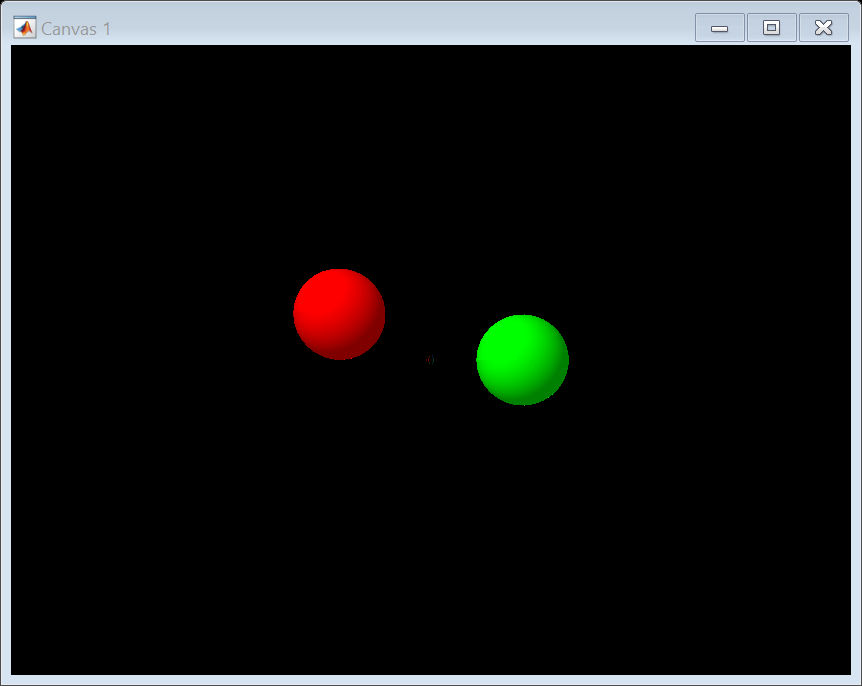

myBallSet(1).Position = [-2 1 0];

The properties of PHYSVIS objects are compatible with all of the usual MATLAB matrix arithmetic operations and functions.

You can find the distance between the two balls,

dist = norm(myBallSet(1).Position - myBallSet(2).Position)

dist = 4.1231

You can find the center of mass of the two ball system,

myBallSet(2).UserData.Mass = 2;
cm = [0 0 0];
for k = 1:length(myBallSet)
    cm = cm + myBallSet(k).UserData.Mass * myBallSet(k).Position;
end
cm = cm / length(myBallSet)

cm =     1.0000    0.5000         0


You can rotate visual objects with their `Rotate` method. Create a box.

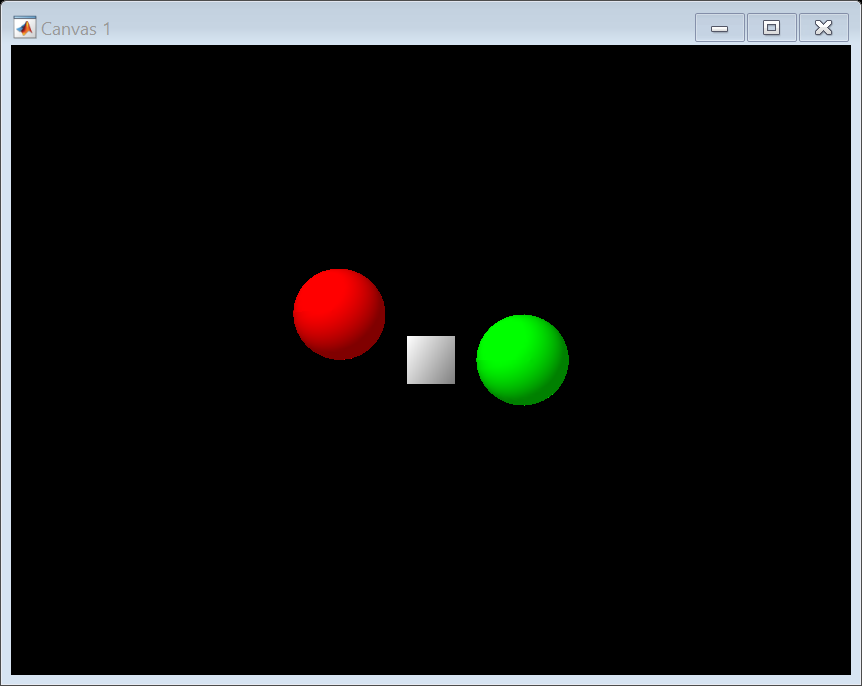

myBox = physvis.Box();

Rotate it by $\pi/4$ radians about the z-axis fixed at the box's position, which happens to be the origin.

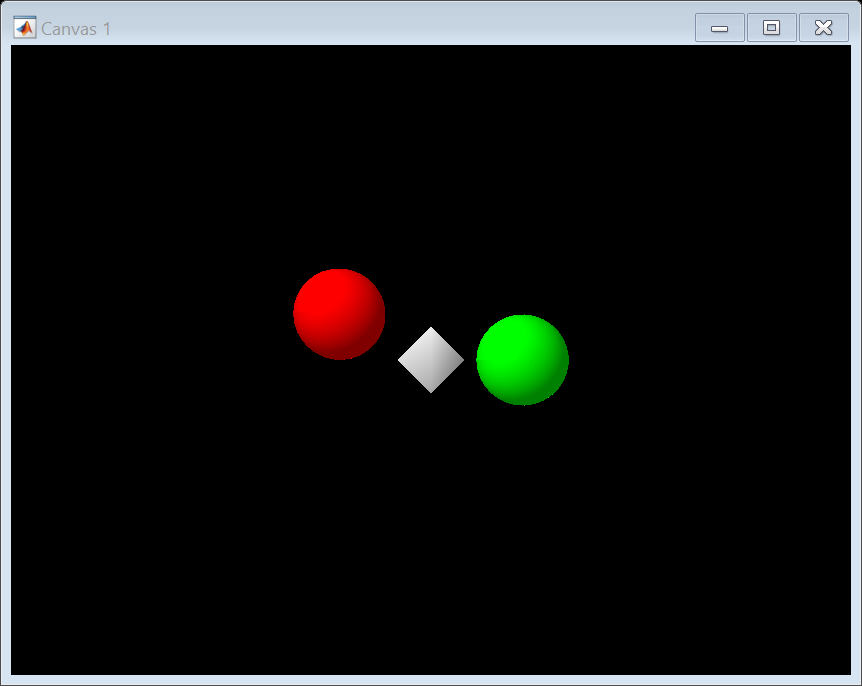

Rotate(myBox, pi/4, [0 0 1]);

Rotate it by $\pi$ radians about the z-axis fixed at the second ball's position.

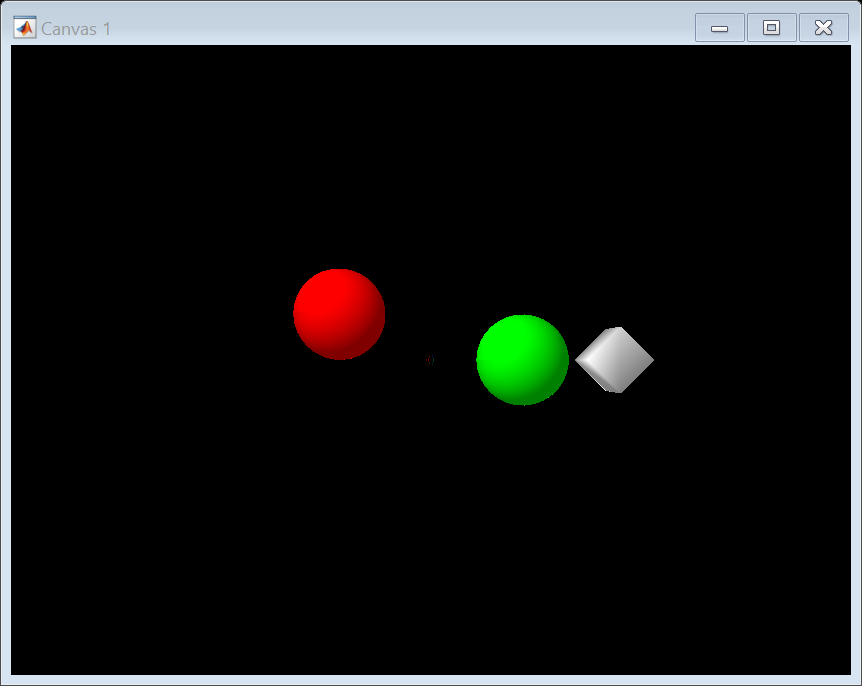

Rotate(myBox, pi, [0 0 1], myBallSet(2).Position);

Rotate it by $\pi/4$ radians about the z-axis fixed at the box's position.

Rotate(myBox, pi/4, [0 0 1]);

© Copyright 2017 The MathWorks, Inc.